# Train Fast R-CNN Stop Sign Detector

Load training data.

data = load('rcnnStopSigns.mat', 'stopSigns', 'fastRCNNLayers')

data = struct with fields:
         stopSigns: [27×2 table]
    fastRCNNLayers: [11×1 nnet.cnn.layer.Layer]


stopSigns = data.stopSigns;
%data2 = load('fast_rcnn_model_res50.mlx')

train_imgs = imageDatastore("pothole_dataset/train")

train_imgs =   ImageDatastore with properties:

                       Files: {
                              ' .../train/img-100_jpg.rf.233751cac3399aa80b5e58a2afbb753a.jpg';
                              ' .../train/img-101_jpg.rf.f213d98946c4f8858a5bf3200c89e39c.jpg';
                              ' .../train/img-102_jpg.rf.16c56ff8f761aec963d9b57aa1b2d3fd.jpg'
                               ... and 462 more
                              }
                     Folders: {
                              ' .../ubuntu1604/matlab_project/FastRCNN_pothole/pothole_dataset/train'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


test_imgs = imageDatastore("pothole_dataset/test")

test_imgs =   ImageDatastore with properties:

                       Files: {
                              ' .../test/img-105_jpg.rf.3fe9dff3d1631e79ecb480ff403bcb86.jpg';
                              ' .../test/img-107_jpg.rf.2e40485785f6e5e2efec404301b235c2.jpg';
                              ' .../test/img-146_jpg.rf.61be25b3053a51f622a244980545df2b.jpg'
                               ... and 64 more
                              }
                     Folders: {
                              ' .../ubuntu1604/matlab_project/FastRCNN_pothole/pothole_dataset/test'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage



gt_train = readtable("pothole_dataset/train/_annotations.csv");
gt_test = readtable("pothole_dataset/test/_annotations.csv");

w_train = gt_train.xmax - gt_train.xmin;
h_train = gt_train.ymax - gt_train.ymin;
w_test = gt_test.xmax - gt_test.xmin;
h_test = gt_test.ymax - gt_test.ymin;

bbox_train = [gt_train.xmin, gt_train.ymax, w_train, h_train]

bbox_train =    175    51    36    14
   189    24    57    20
   278   160   121   160
    19   190   278   104
    60   299   118    99
     1   254    42    24
   162    75    28    19
   123    86    36    17
   338   192    61    30
   283   442   201   171


bbox_test = [gt_test.xmin, gt_test.ymax, w_test, h_test]

bbox_test =     30   299   576   260
   259   432   233   146
   353   482    95   103
   282   605    85    75
    52   298   399   204
   149   183   111    46
    83    96    74    18
   272   164     0     1
   245   410   163   116
   359   310   103    89



blds_train = boxLabelDatastore(bbox_train)

Error using boxLabelDatastore (line 234)
Expected input number 1, trainingData, to be one of these types:

table

Instead its type was double.

blds_test = boxLabelDatastore(bbox_test)

%blds_train = boxLabelDatastore(gt_train())


fastRCNNLayers = data.fastRCNNLayers

Add fullpath to image files.

% stopSigns.imageFilename = fullfile(toolboxdir('vision'),'visiondata', ...
%    stopSigns.imageFilename);

Randomly shuffle data for training.

rng(0);
shuffledIdx = randperm(height(stopSigns));
stopSigns = stopSigns(shuffledIdx,:);

Create an imageDatastore using the files from the table.

imds = imageDatastore(stopSigns.imageFilename);

Create a boxLabelDatastore using the label columns from the table.

blds = boxLabelDatastore(stopSigns(:,2:end));

Combine the datastores.

ds = combine(imds, blds);

The stop sign training images have different sizes. Preprocess the data to resize the image and boxes to a predefined size.

ds = transform(ds,@(data)preprocessData(data,[920 968 3]));

Set the network training options.

options = trainingOptions('sgdm', ...
    'MiniBatchSize', 5, ...
    'InitialLearnRate', 1e-3, ...
    'MaxEpochs', 10, ...
    'CheckpointPath', tempdir);

Train the Fast R-CNN detector. Training can take a few minutes to complete.

frcnn = trainFastRCNNObjectDetector(ds, fastRCNNLayers , options, ...
    'NegativeOverlapRange', [0 0.1], ...
    'PositiveOverlapRange', [0.7 1]);

*******************************************************************
Training a Fast R-CNN Object Detector for the following object classes:

* stopSign

--> Extracting region proposals from training datastore...done.

Training on single GPU.
Initializing input data normalization.
|=======================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |      Rate       |
|=======================================================================================================|
|       1 |           1 |       00:00:21 |       0.1470 |       99.69% |         1.04 |          0.0010 |
|      10 |          30 |       00:03:38 |       0.1255 |      100.00% |         0.90 |          0.0010 |
|==================================================================================

Test the Fast R-CNN detector on a test image.

img = imread('stopSignTest.jpg');

Run the detector.

[bbox, score, label] = detect(frcnn, img);

Display detection results.

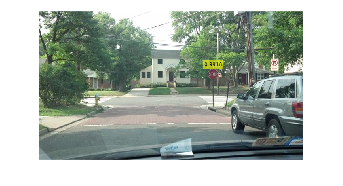

detectedImg = insertObjectAnnotation(img,'rectangle',bbox,score);
figure
imshow(detectedImg)

## Supporting Functions

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
scale = targetSize(1:2)./size(data{1},[1 2]);
data{1} = imresize(data{1},targetSize(1:2));
bboxes = round(data{2});
data{2} = bboxresize(bboxes,scale);
end